## Automotive Adaptive Cruise Control Using FMCW Technology

In an ACC setup, the maximum range the radar needs to monitor is around 200 m and the system needs to be able to distinguish two targets that are 1 meter apart. From these requirements, one can compute the waveform parameters.

fc = 77e9;
c = 3e8;
lambda = c/fc

lambda = 0.0039

range_max = 200;
tm = 5.5*range2time(range_max,c)

tm = 7.3333e-06

range_res = 1;
bw = range2bw(range_res,c)

bw = 150000000

sweep_slope = bw/tm

sweep_slope = 7.5000e+10

Because an FMCW signal often occupies a huge bandwidth, setting the sample rate blindly to twice the bandwidth often stresses the capability of A/D converter hardware. To address this issue, one can often choose a lower sample rate. Two things can be considered here:

- For a complex sampled signal, the sample rate can be set to the same as the bandwidth.

- FMCW radars estimate the target range using the beat frequency embedded in the dechirped signal. The maximum beat frequency the radar needs to detect is the sum of the beat frequency corresponding to the maximum range and the maximum Doppler frequency. Hence, the sample rate only needs to be twice the maximum beat frequency.

In this example, the beat frequency corresponding to the maximum range is given by

fr_max = range2beat(range_max,sweep_slope,c)

fr_max = 100000

In addition, the maximum speed of a traveling car is about 230 km/h. Hence the maximum Doppler shift and the maximum beat frequency can be computed as

v_max = 230*1000/3600

v_max = 63.8889

fd_max = speed2dop(2*v_max,lambda)

fd_max = 3.2796e+04


fb_max = fr_max+fd_max

fb_max = 1.3280e+05

This example adopts a sample rate of the larger of twice the maximum beat frequency and the bandwidth.

fs = max(2*fb_max,bw)

fs = 150000000

The following table summarizes the radar parameters.

`System parameters            Value`

`----------------------------------`

`Operating frequency (GHz)    77`

`Maximum target range (m)     200`

`Range resolution (m)         1`

`Maximum target speed (km/h)  230`

`Sweep time (microseconds)    7.33`

`Sweep bandwidth (MHz)        150`

`Maximum beat frequency (MHz) 27.30`

`Sample rate (MHz)            150`

With all the information above, one can set up the FMCW waveform used in the radar system.

hwav = phased.FMCWWaveform('SweepTime',tm,'SweepBandwidth',bw,...
    'SampleRate',fs)

hwav =   phased.FMCWWaveform with properties:

        SampleRate: 150000000
         SweepTime: 7.3333e-06
    SweepBandwidth: 150000000
    SweepDirection: 'Up'
     SweepInterval: 'Positive'
      OutputFormat: 'Sweeps'
         NumSweeps: 1


This is a up-sweep linear FMCW signal, often referred to as sawtooth shape. One can examine the time-frequency plot of the generated signal.

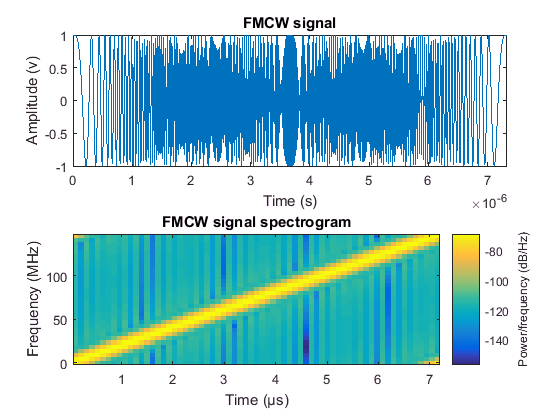

s = step(hwav);
subplot(211); plot(0:1/fs:tm-1/fs,real(s));
xlabel('Time (s)'); ylabel('Amplitude (v)');
title('FMCW signal'); axis tight;
subplot(212); spectrogram(s,32,16,32,fs,'yaxis');
title('FMCW signal spectrogram');

## Target Model

The target of an ACC radar is usually a car in front of it. This example assumes the target car is moving 50 m ahead of the car with the radar, at a speed of 96 km/h along the x-axis. 

The radar cross section of a car, according to [1], can be computed based on the distance between the radar and the target car.

car_dist = 43;
car_speed = 96*1000/3600;
car_rcs = db2pow(min(10*log10(car_dist)+5,20));

hcar = phased.RadarTarget('MeanRCS',car_rcs,'PropagationSpeed',c,...
    'OperatingFrequency',fc);
hcarplatform = phased.Platform('InitialPosition',[car_dist;0;0.5],...
    'Velocity',[car_speed;0;0])

hcarplatform =   phased.Platform with properties:

                  MotionModel: 'Velocity'
              InitialPosition: [3x1 double]
               VelocitySource: 'Property'
                     Velocity: [3x1 double]
       InitialOrientationAxes: [3x3 double]
    OrientationAxesOutputPort: 0


The propagation model is assumed to be free space.

hchannel = phased.FreeSpace('PropagationSpeed',c,...
    'OperatingFrequency',fc,'SampleRate',fs,'TwoWayPropagation',true)

hchannel =   phased.FreeSpace with properties:

         PropagationSpeed: 300000000
       OperatingFrequency: 7.7000e+10
        TwoWayPropagation: 1
               SampleRate: 150000000
    MaximumDistanceSource: 'Auto'


## Radar System Setup

The rest of the radar system includes the transmitter, the receiver, and the antenna. This example uses the parameters presented in [1]. Note that this example models only main components and omits the effect from other components, such as coupler and mixer. In addition, for the sake of simplicity, the antenna is assumed to be isotropic and the gain of the antenna is included in the transmitter and the receiver.

ant_aperture = 6.06e-4;                         % in square meter
ant_gain = aperture2gain(ant_aperture,lambda);  % in dB

tx_ppower = db2pow(5)*1e-3;                     % in watts
tx_gain = 9+ant_gain;                           % in dB

rx_gain = 15+ant_gain;                          % in dB
rx_nf = 4.5;                                    % in dB

htx = phased.Transmitter('PeakPower',tx_ppower,'Gain',tx_gain)

htx =   phased.Transmitter with properties:

             PeakPower: 0.0032
                  Gain: 36.0042
            LossFactor: 0
       InUseOutputPort: 0
    CoherentOnTransmit: 1


hrx = phased.ReceiverPreamp('Gain',rx_gain,'NoiseFigure',rx_nf,...
    'SampleRate',fs)

hrx =   phased.ReceiverPreamp with properties:

                    Gain: 42.0042
              LossFactor: 0
             NoiseMethod: 'Noise temperature'
             NoiseFigure: 4.5000
    ReferenceTemperature: 290
              SampleRate: 150000000
         NoiseComplexity: 'Complex'
         EnableInputPort: 0
     PhaseNoiseInputPort: 0
              SeedSource: 'Auto'


Automotive radars are generally mounted on a vehicles, so they are often in motion. This example assumes the radar is traveling at a speed of 100 km/h along x-axis. So the target car is approaching the radar at a relative speed of 4 km/h.

radar_speed = 100*1000/3600;
hradarplatform = phased.Platform('InitialPosition',[0;0;0.5],...
    'Velocity',[radar_speed;0;0])

hradarplatform =   phased.Platform with properties:

                  MotionModel: 'Velocity'
              InitialPosition: [3x1 double]
               VelocitySource: 'Property'
                     Velocity: [3x1 double]
       InitialOrientationAxes: [3x3 double]
    OrientationAxesOutputPort: 0


## Radar Signal Simulation

As briefly mentioned in earlier sections, an FMCW radar measures the range by examining the beat frequency in the dechirped signal. To extract this frequency, a dechirp operation is performed by mixing the received signal with the transmitted signal. After the mixing, the dechirped signal contains only individual frequency components that correspond to the target range.

In addition, even though it is possible to extract the Doppler information from a single sweep, the Doppler shift is often extracted among several sweeps because within one pulse, the Doppler frequency is indistinguishable from the beat frequency. To measure the range and Doppler, an FMCW radar typically performs the following operations:

- The waveform generator generates the FMCW signal.

- The transmitter and the antenna amplify the signal and radiate the signal into space.

- The signal propagates to the target, gets reflected by the target, and travels back to the radar.

- The receiving antenna collects the signal.

- The received signal is dechirped and saved in a buffer.

- Once a certain number of sweeps fill the buffer, the Fourier transform is performed in both range and Doppler to extract the beat frequency as well as the Doppler shift. One can then estimate the range and speed of the target using these results. Range and Doppler can also be shown as an image and give an intuitive indication of where the target is in the range and speed domain.

The next section simulates the process outlined above. A total of 64 sweeps are simulated and a range Doppler response is generated at the end.

During the simulation, a spectrum analyzer is used to show the spectrum of each received sweep as well as its dechirped counterpart.

hspec = dsp.SpectrumAnalyzer('SampleRate',fs,...
    'PlotAsTwoSidedSpectrum',true,...
    'Title','Spectrum for received and dechirped signal',...
    'ShowLegend',true)

hspec =   dsp.SpectrumAnalyzer with properties:

                         Name: 'Spectrum Analyzer'
                NumInputPorts: 1
                 SpectrumType: 'Power'
                   SampleRate: 150000000
                FrequencySpan: 'Full'
    FrequencyResolutionMethod: 'RBW'
                    RBWSource: 'Auto'
               OverlapPercent: 0
                       Window: 'Hann'
             SpectralAverages: 1
                   PowerUnits: 'dBm'
                ReferenceLoad: 1
             PlotMaxHoldTrace: 0
             PlotMinHoldTrace: 0
              PlotNormalTrace: 1
                     PlotType: 'Line'
       PlotAsTwoSidedSpectrum: 1
               FrequencyScale: 'Linear'
              FrequencyOffset: 0
                        Title: 'Spectrum for received and dechirped signal'
                      YLimits: [-80 20]
                       YLabel: ''
                   ShowLeg

Next, run the simulation loop. 

radar_pos =          0
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0002
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0004
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0006
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0008
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0010
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0012
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0014
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0016
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0018
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0020
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0022
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0024
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0026
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0029
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0031
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0033
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0035
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0037
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0039
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0041
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0043
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0045
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0047
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0049
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0051
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0053
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0055
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0057
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0059
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0061
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0063
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0065
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0067
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0069
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0071
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0073
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0075
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0077
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0079
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0081
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0084
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0086
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0088
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0090
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0092
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0094
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0096
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0098
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0100
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0102
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0104
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0106
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0108
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0110
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0112
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0114
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0116
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0118
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0120
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0122
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0124
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0126
         0
    0.5000


radar_vel =    27.7778
         0
         0


radar_pos =     0.0128
         0
    0.5000


radar_vel =    27.7778
         0
         0


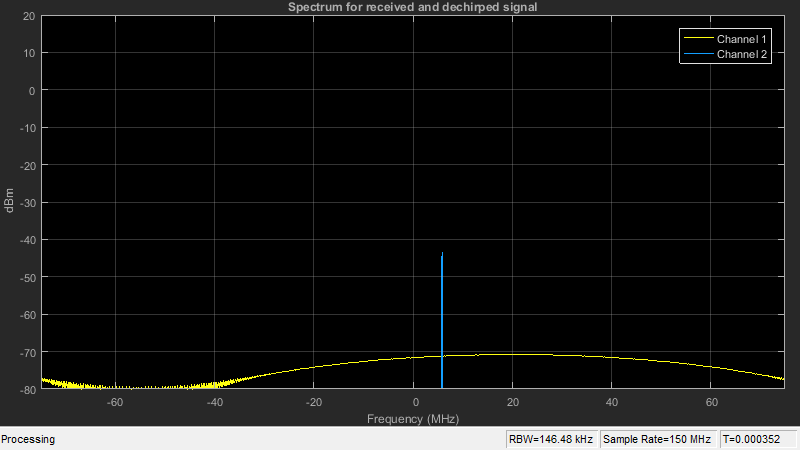

Nsweep = 64;
xr = complex(zeros(hwav.SampleRate*hwav.SweepTime,Nsweep));

for m = 1:Nsweep
    [radar_pos,radar_vel] = step(...
        hradarplatform,hwav.SweepTime)       % Radar moves during sweep
    [tgt_pos,tgt_vel] = step(hcarplatform,... 
        hwav.SweepTime);                      % Car moves during sweep
    x = step(hwav);                           % Generate the FMCW signal
    xt = step(htx,x);                         % Transmit the signal
    xt = step(hchannel,xt,radar_pos,tgt_pos,...
        radar_vel,tgt_vel);                   % Propagate the signal
    xt = step(hcar,xt);                       % Reflect the signal
    xt = step(hrx,xt);                        % Receive the signal
    xd = dechirp(xt,x);                       % Dechirp the signal
    
    step(hspec,[xt xd]);                      % Visualize the spectrum
    
    xr(:,m) = xd;                             % Buffer the dechirped signal
end

From the spectrum scope, one can see that although the received signal is wideband (channel 1), sweeping through the entire bandwidth, the dechirped signal becomes narrowband (channel 2). 

## Range and Doppler Estimation

Before estimating the value of the range and Doppler, it may be a good idea to take a look at the zoomed range Doppler response of all 64 sweeps.

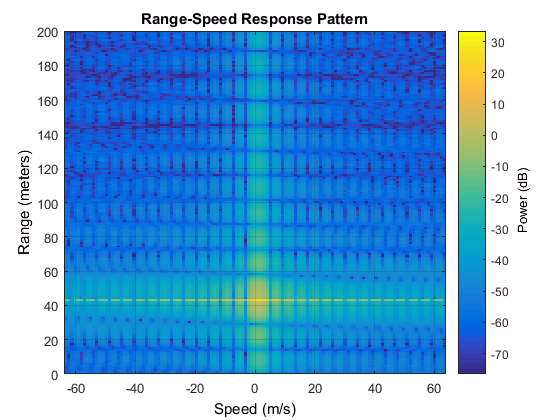

hrdresp = phased.RangeDopplerResponse('PropagationSpeed',c,...
    'DopplerOutput','Speed','OperatingFrequency',fc,'SampleRate',fs,...
    'RangeMethod','FFT','SweepSlope',sweep_slope,...
    'RangeFFTLengthSource','Property','RangeFFTLength',2048,...
    'DopplerFFTLengthSource','Property','DopplerFFTLength',256);

clf;
plotResponse(hrdresp,xr);                     % Plot range Doppler map
axis([-v_max v_max 0 range_max])

clim = caxis;

From the range Doppler response, one can see that the car in front is a bit more than 40 m away and appears almost static. This is expected because the radial speed of the car relative to the radar is only 4 km/h, which translates to a mere 1.11 m/s.

There are many ways to estimate the range and speed of the target car. For example, one can choose almost any spectral analysis method to extract both the beat frequency and the Doppler shift. This example uses the root MUSIC algorithm to extract both the beat frequency and the Doppler shift.

As a side note, although the received signal is sampled at 150 MHz so the system can achieve the required range resolution, after the dechirp, one only needs to sample it at a rate that corresponds to the maximum beat frequency. Since the maximum beat frequency is in general less than the required sweeping bandwidth, the signal can be decimated to alleviate the hardware cost. The following code snippet shows the decimation process.

Dn = fix(fs/(2*fb_max));
for m = size(xr,2):-1:1
    xr_d(:,m) = decimate(xr(:,m),Dn,'FIR');
end
fs_d = fs/Dn;

To estimate the range, firstly, the beat frequency is estimated using the coherently integrated sweeps and then converted to the range.

fb_rng = rootmusic(pulsint(xr_d,'coherent'),1,fs_d);
rng_est = beat2range(fb_rng,sweep_slope,c)

rng_est = 42.9977

Second, the Doppler shift is estimated across the sweeps at the range where the target is present.

peak_loc = val2ind(rng_est,c/(fs_d*2));
fd = -rootmusic(xr_d(peak_loc,:),1,1/tm);
v_est = dop2speed(fd,lambda)/2

v_est = 1.0901

Note that both range and Doppler estimation are quite accurate.

## Range Doppler Coupling Effect

One issue associated with linear FM signals, such as an FMCW signal, is the range Doppler coupling effect. As discussed earlier, the target range corresponds to the beat frequency. Hence, an accurate range estimation depends on an accurate estimate of beat frequency. However, the presence of Doppler shift changes the beat frequency, resulting in a biased range estimation. 

For the situation outlined in this example, the range error caused by the relative speed between the target and the radar is

deltaR = rdcoupling(fd,sweep_slope,c)

deltaR = -0.0041

This error is so small that we can safely ignore it. 

Even though the current design is achieving the desired performance, one parameter warrants further attention. In the current configuration, the sweep time is about 7 microseconds. Therefore, the system needs to sweep a 150 MHz band within a very short period. Such an automotive radar may not be able to meet the cost requirement. Besides, given the velocity of a car, there is no need to make measurements every 7 microseconds. Hence, automotive radars often use a longer sweep time. For example, the waveform used in [2] has the same parameters as the waveform designed in this example except a sweep time of 2 ms.

A longer sweep time makes the range Doppler coupling more prominent. To see this effect, first reconfigure the waveform to use 2 ms as the sweep time.

hwavtr = clone(hwav);
release(hwavtr);
tm = 2e-3;
hwavtr.SweepTime = tm;
sweep_slope = bw/tm;

Now calculate the range Doppler coupling. 

deltaR = rdcoupling(fd,sweep_slope,c)

deltaR = -1.1191

A range error of 1.14 m can no longer be ignored and needs to be compensated. Naturally, one may think of doing so following the same procedure outlined in earlier sections, estimating both range and Doppler, figuring out the range Doppler coupling from the Doppler shift, and then remove the error from the estimate.

Unfortunately this process doesn't work very well with the long sweep time. The longer sweep time results in a lower sampling rate across the sweeps, thus reducing the radar's capability of unambiguously detecting high speed vehicles. For instance, using a sweep time of 2 ms, the maximum unambiguous speed the radar system can detect using the traditional Doppler processing is

v_unambiguous = dop2speed(1/(2*tm),lambda)/2

v_unambiguous = 0.4870

The unambiguous speed is only 0.48 m/s, which means that the relative speed, 1.11 m/s, cannot be unambiguously detected. This means that not only the target car will appear slower in Doppler processing, the range Doppler coupling also cannot be correctly compensated.

One way to resolve such ambiguity without Doppler processing is to adopt a triangle sweep pattern. Next section shows how the triangle sweep addresses the issue.

## Triangular Sweep

In a triangular sweep, there are one up sweep and one down sweep to form one period, as shown in the following figure.

<<FMCWExample_trisweep.png>>

The two sweeps have the same slope except different signs. From the figure, one can see that the presence of Doppler frequency, $f_d$, affects the beat frequencies ($f_{bu}$ and $f_{bd}$) differently in up and down sweeps. Hence by combining the beat frequencies from both up and down sweep, the coupling effect from the Doppler can be averaged out and the range estimate can be obtained without ambiguity.

First, set the waveform to use triangular sweep.

hwavtr.SweepDirection = 'Triangle';

Now simulate the signal return. Because of the longer sweep time, fewer sweeps (16 vs. 64) are collected before processing.

Nsweep = 16;
xr = helperFMCWSimulate(Nsweep,hwavtr,hradarplatform,hcarplatform,...
    htx,hchannel,hcar,hrx);

The up sweep and down sweep are processed separately to obtain the beat frequencies corresponding to both up and down sweep.

fbu_rng = rootmusic(pulsint(xr(:,1:2:end),'coherent'),1,fs);
fbd_rng = rootmusic(pulsint(xr(:,2:2:end),'coherent'),1,fs);

Using both up sweep and down sweep beat frequencies simultaneously, the correct range estimate is obtained.

rng_est = beat2range([fbu_rng fbd_rng],sweep_slope,c)

rng_est = 42.9831

Moreover, the Doppler shift and the velocity can also be recovered in a similar fashion.

fd = -(fbu_rng+fbd_rng)/2;
v_est = dop2speed(fd,lambda)/2

v_est = 1.1217

The estimated range and velocity match the true values, 43 m and 1.11 m/s, very well.

## Two-ray Propagation

To complete the discussion, in reality, the actual signal propagation between the radar and the target vehicle is more complicated than what is modeled so far. For example, the radio wave can also arrive at the target vehicle via reflections. A simple yet widely used model to describe such a multipath scenario is a two-ray model, where the signal propagates from the radar to the target vehicle via two paths, one direct path and one reflected path off the road, as shown in the following figure.

<<FMCWExample_tworay.png>>

The reflection off the road impacts the phase of the signal and the receiving signal at the target vehicle is a coherent combination of the signals via the two paths. Same thing happens on the return trip too where the reflected signal off the target vehicle travels back to the radar. Hence depending on the distance between the vehicles, the signals from different paths may add constructively or destructively, making signal strength fluctuating over time. Such fluctuation can pose some challenge in the successive detection stage.

To showcase the multipath effect, next section uses the two ray channel model to propagate the signal between the radar and the target vehicle.

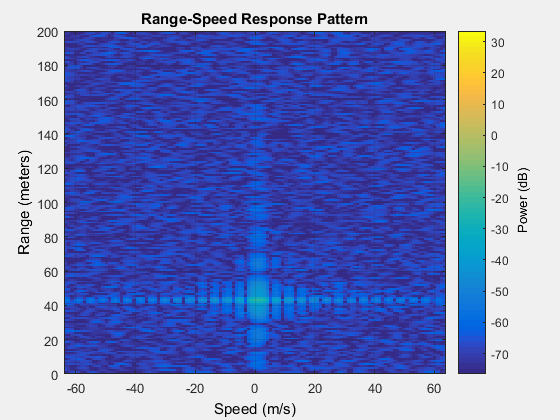

chant = phased.TwoRayChannel('PropagationSpeed',c,...
    'OperatingFrequency',fc,'SampleRate',fs);
chanr = phased.TwoRayChannel('PropagationSpeed',c,...
    'OperatingFrequency',fc,'SampleRate',fs);
Nsweep = 64;
xr = helperFMCWTwoRaySimulate(Nsweep,hwav,hradarplatform,hcarplatform,...
    htx,chant,chanr,hcar,hrx);
plotResponse(hrdresp,xr);                     % Plot range Doppler map
axis([-v_max v_max 0 range_max]);
caxis(clim);

With all settings remaining same, the comparison of the resulting range-Doppler map with two-ray propagation and the range-Doppler map obtained before with a line of sight (LOS) propagation channel suggests that the signal strength dropped almost 40 dB, which is significant. Therefore, such effect must be considered during the design. One possible choice is to form a very sharp beam on the vertical direction to null out the reflections.

## Summary

This example shows how to use FMCW signal to perform range and Doppler estimation in an automotive automatic cruise control application. The example also shows how to generate a range Doppler map from the received signal and discussed how to use triangle sweep to compensate for the range Doppler coupling effect for the FMCW signal. Finally, the effect on the signal level due to the multipath propagation is discussed.

## References

[1] Karnfelt, C. et al.. *77 GHz ACC Radar Simulation Platform*, IEEE International Conferences on Intelligent Transport Systems Telecommunications (ITST), 2009.

[2] Rohling, H. and M. Meinecke. *Waveform Design Principle for Automotive Radar Systems*, Proceedings of CIE International Conference on Radar, 2001.